# Relative Velocity

## 
$$v_A = v_B +v_{A/B}$$


## 
$$u_{A/B} = \omega*r$$


## 
$$v_{A/B} = \omega \times r     \rightarrow crossprodukt$$


## 
$$v_A = v_B +\omega \times r$$


# Opgave 5/48

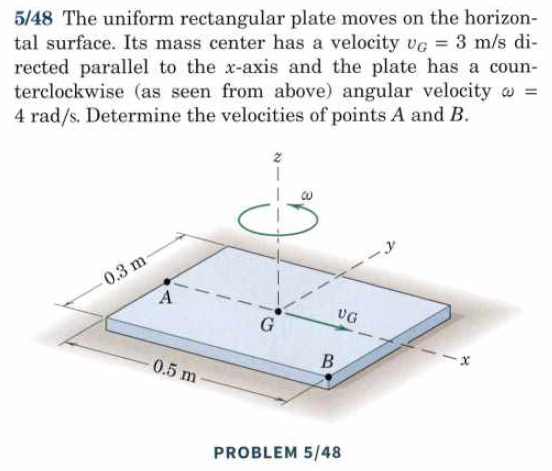

V_B = V_G

Omega = 4 rad/s

Vores vektorer for punkterne A & B er som følgende:

- A: [-0.25;0;0]

- B: [0.25;-0.15;0]

vg = [3;0;0];
vB = vg;

omega = [0;0;4];

A = [-0.25;0;0];
B = [0.25;-0.15;0];

V_a = vB + cross(omega,A)

V_a =      3
    -1
     0


V_b = vB + cross(omega,B)

V_b =     3.6000
    1.0000
         0


# Opgave 5/66

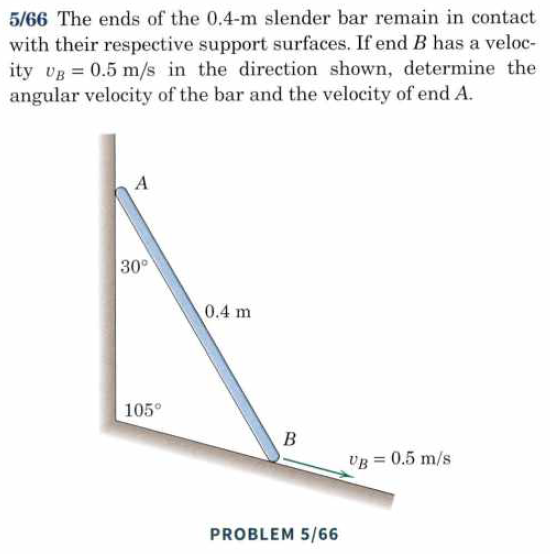

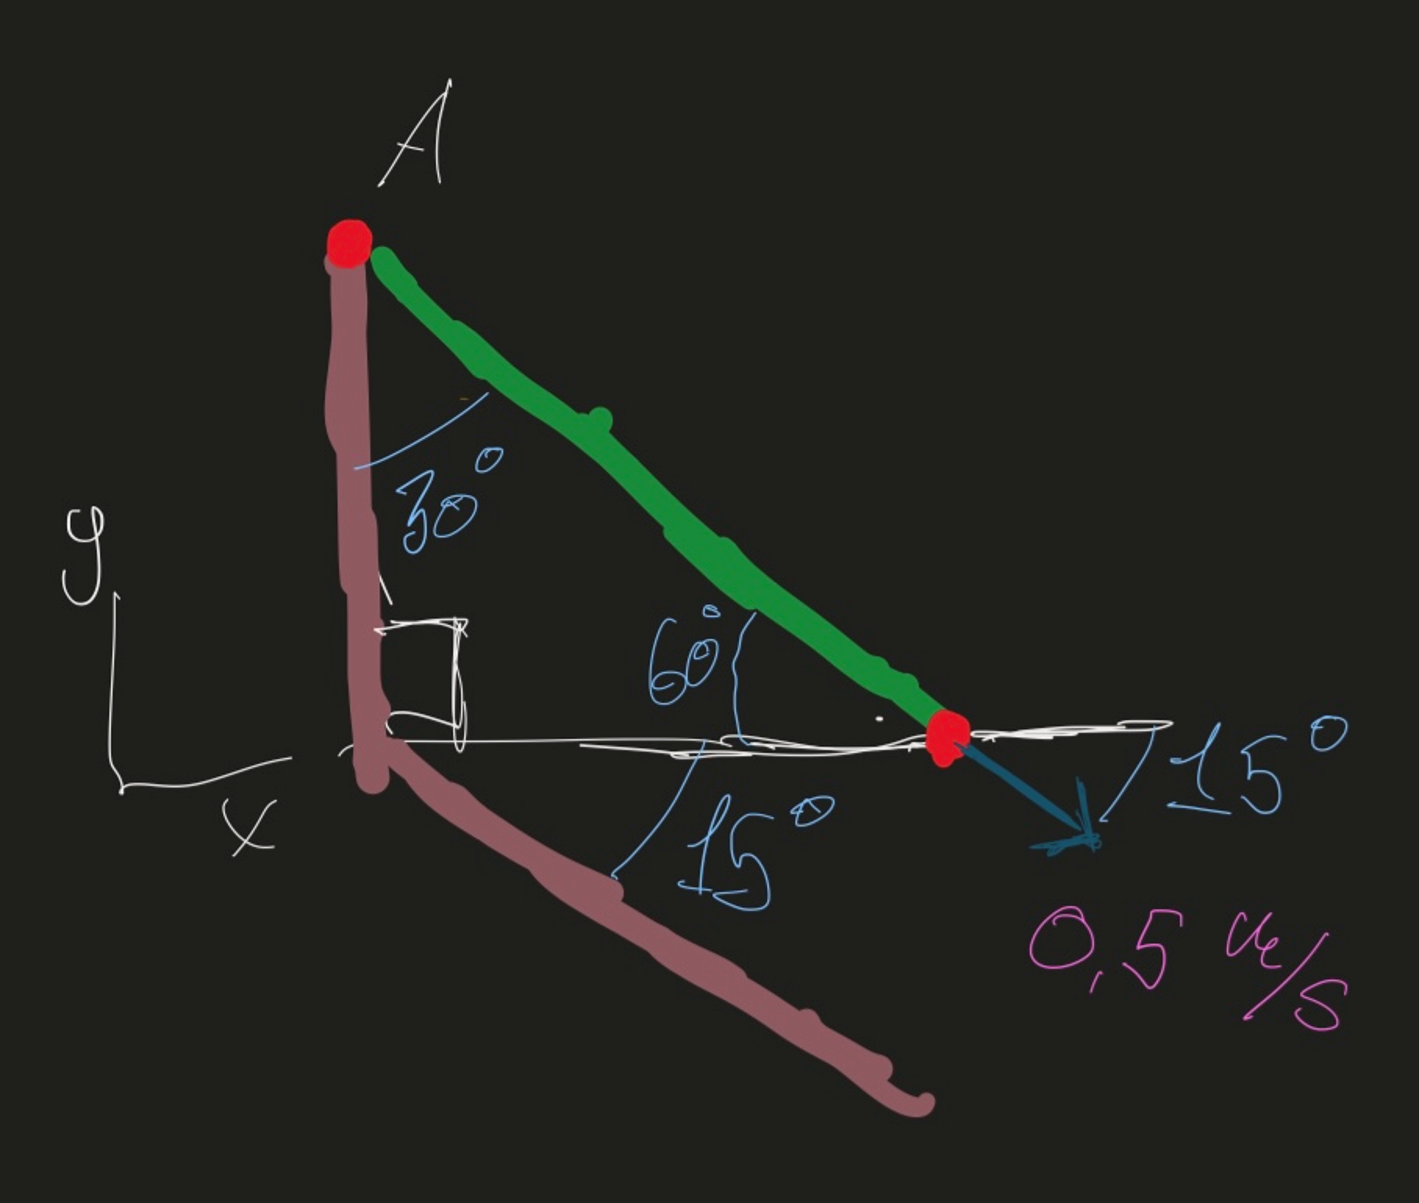

Vinkel A = 30°

Vinkel B = 105°

Vinkel C = 45°

a = (sin(30)*0.4m)/sin(105)

b = (sin(45)*0.4m)sin(105)

V_B = 0.5 m/s

Det ønskes at vi finder:

- Omega

- V_A

# Undervisning D. 28/11

- Vibration: Frie udæmpede svingninger

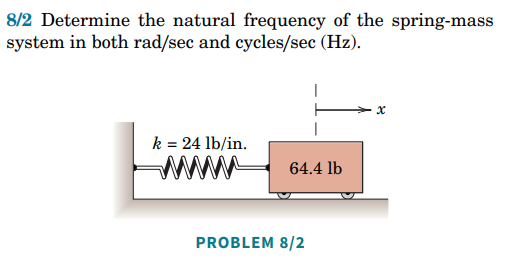

k = 4500 n/m

m = 20 kg

Bestem den naturlige frekvens i både rad/sec & Hz

u = symunit;
k = 4500;
m = 20;

omega = sqrt(k/m) 

omega = 15

ln    = omega/(2*pi)

ln = 2.3873

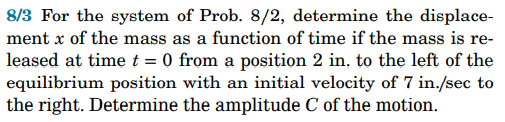

Informationer:


$$x(0) = -30 mm = x_0$$



$$\dot{x}(0) = 120 mm/s = v_0$$


Formlen, som vi skal anvende til at finde C, amplituden:


$$C = \sqrt{x_0^2 + (\dot{x_0}/\omega_n)^2}$$



$$\phi = arctan( (x_0*\omega_n)/\dot{x_0} )$$


x_0 = -30;
V_0 = 120;

C = vpa(sqrt(x_0^2 + (V_0/omega)^2))

$$C = 31.048349392520047457724923534346$$

Phi = vpa(atan((x_0 * omega)/V_0))

$$Phi = -1.3101939350475557688469052664004$$

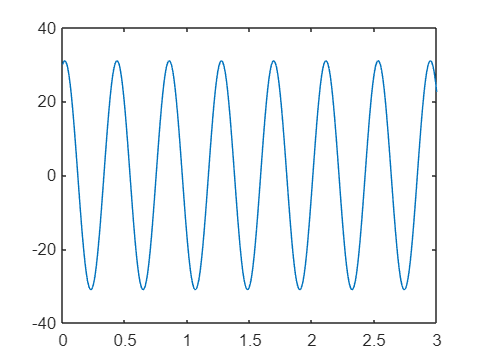


t = linspace(0,3,300);
x = @(t) C * sin(omega*t - Phi);

plot(t,x(t))

Så bliver afstanden som funktion af tid: 


$$x(t) = 31.048 * sin(15 \frac{Rad}{Sec}*(t) - 1.31*Rad)$$


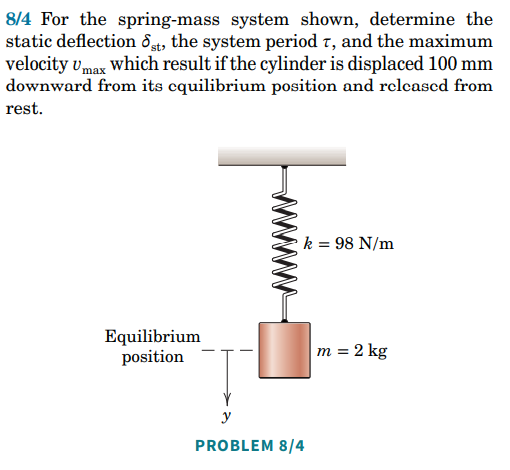

Informationer:


$$k = 98 N/m$$



$$m = 2 kg$$



$$x_0 = 100 mm$$


Formler:


$$C = \sqrt{A^2 + B^2} \rightarrow x_0 = A*cos(\omega_n * 0) + 0 \rightarrow A = x_0$$



$$C = 100$$



$$\sigma_{st} = \frac{Weight}{k} \rightarrow \frac{(m*g)}{k}$$



$$t = \frac{2*\pi}{\omega}$$



$$\omega_n = \sqrt(\frac{k}{m})$$


k = 98;
m = 2;

g = 9.81;

x_0 = 100

x_0 = 100

V_0 = 0

V_0 = 0


omega = sqrt(k/m)

omega = 7


C = sqrt(x_0^2+(V_0/omega)^2)

C = 100


psi = atan(x_0*omega/V_0)

psi = 1.5708


Statisk_Deflektion = vpa(((m*g)/k),4)

$$Statisk\_Deflektion = 0.2002$$


tid_mellem_amplitude = (2*pi)/omega

tid_mellem_amplitude = 0.8976


syms x(t)

x(t) = C * sin(omega*t + psi)

$$x(t) = 100\,\sin\left(7\,t+\frac{\pi }{2}\right)$$


dxdt(t) = diff(x(t),t)

$$dxdt(t) = 700\,\cos\left(7\,t+\frac{\pi }{2}\right)$$

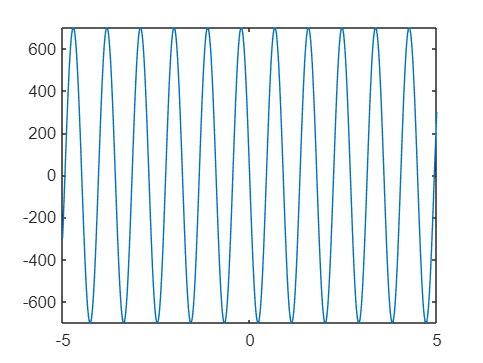


fplot(dxdt) % Hastighedsgraf


tid_hvor_V_max = solve(x(t) == 0,t) % Tiden, hvor vi har den højeste hastighed

$$tid\_hvor\_V\_max = \frac{\pi }{14}$$


vpa(dxdt(tid_hvor_V_max),3) % Angiver Maksimale hastighed.

$$ans = -700.0$$

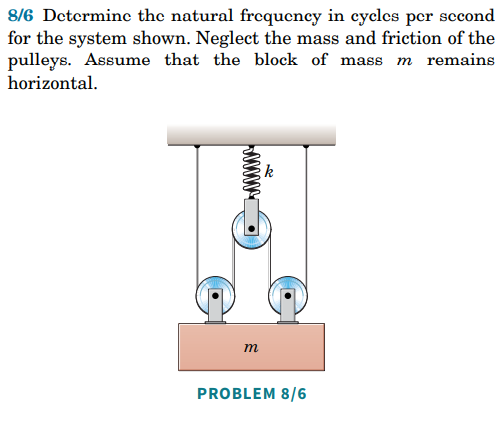

Tjek Brightspace.

Næste opgave 8/12